## Heat flux

In this section we will investigate the heat flux generated by the two bodies 

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice5'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = 'flux.in'; % Nom du fichier d'entree de base

graphSet

cmd = sprintf('wsl %s%s %s dt=%.15g output=%s', repertoire, executable, input,0.001, 'flux');
disp(cmd)

wsl ./Exercice5 flux.in dt=0.001 output=flux


system(cmd);

	L=0.1
	xa=0.02
	xb=0.04
	xc=0.075
	xd=0.085
	ya=0.03
	yb=0.08
	Tc=200
	Tf=-100
	Tb=0
	kappa=1.2
	rho=1.2
	Ccoef=1000
	tfin=1
	eps=10
	N=40
	dt=0.001
	output=flux
10
32000
21760
15616
11733
9156.77
7371.02
6183.46
5669.28
5190.08
4755.78
4367.24
4021.5
3714.27
3441.01
3197.44
2979.7
2784.45
2608.77
2450.17
2338.3
2247.58
2161.09
2078.81
2000.65
1926.46
1856.08
1789.33
1726
1665.92
1608.89
1554.72
1503.26
1454.32
1407.76
1363.42
1321.18
1280.89
1242.43
1211.98
1184.62
1157.95
1131.96
1106.63
1081.96
1057.92
1034.5
1011.68
989.446
967.776
946.654
926.065
905.99
886.415
867.323
848.7
830.53
812.8
795.495
778.603
762.112
746.008
730.281
714.92
699.913
685.25
670.922
656.919
643.231
629.852
616.77
603.98
591.473
579.241
567.277
555.575
544.127
532.928
521.971
511.25
500.759
490.493
480.447
470.614
460.99
451.57
442.349
433.323
424.487
415.837
409.417
403.825
398.335
392.945
387.65
382.45
377.341
372.321
367.388
362.539
357.772
353.086
348.478
343.946
339.489
335.104
330.79
326.545
322.367
3


dataT = load('flux_T.out');
dataP = load('flux_P.out');
        
x = dataT(:,1);
y = dataT(:,2);
T = dataT(:,3);

t = dataP(:,1);
Pc = dataP(:,2);
Pf = dataP(:,3);
Ptot = dataP(:,4);

N = sqrt(length(x));

x = reshape(x,[N,N]);
y = reshape(y,[N,N]);
T = reshape(T,[N,N]);



Finite differences:

We compute the difference between each column and divide by $\Delta x$ thus giving $j_x$ and then to the same for the lines giving $j_y
$

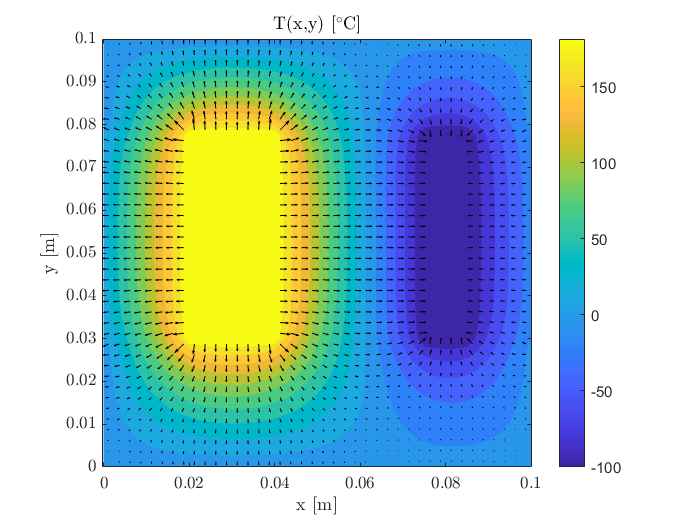


h = x(2) - x(3);

jx = diff(T,1,1);
jy = -diff(T,1,2);

jx = jx /h;
jy = jy /h;

jxc = ones(length(x)-1,length(x)-1);
jyc = ones(length(x)-1,length(x)-1);

for i= 1:length(x)-1
    for j = 1:length(x)-1
        
        jxc(i,j) = (jx(i,j+1)+jx(i,j))*0.5;
        jyc(i,j) = (jy(i+1,j)+jy(i,j))*0.5;
    end
end


X = dataT(1:N,1);
Y = dataT(1:N:N*N,2);

Xmid = X(1:N-1)-h/2;
Ymid = Y(1:N-1)+h/2;

jnorm = sqrt(jxc.^2+jyc.^2);

% Temperature :
figure
contourf(X,Y,T',15,'LineStyle','None'), hold on
stride = 1; % (affiche 1 point sur [stride] dans chaque dimension)
quiver(Xmid(1:stride:end,1:stride:end),Ymid(1:stride:end,1:stride:end),jxc(1:stride:end,1:stride:end)',jyc(1:stride:end,1:stride:end)','k')
xlabel('x [m]')
ylabel('y [m]')
title('T(x,y) [$^{\circ}$C]')
colorbar
axis equal

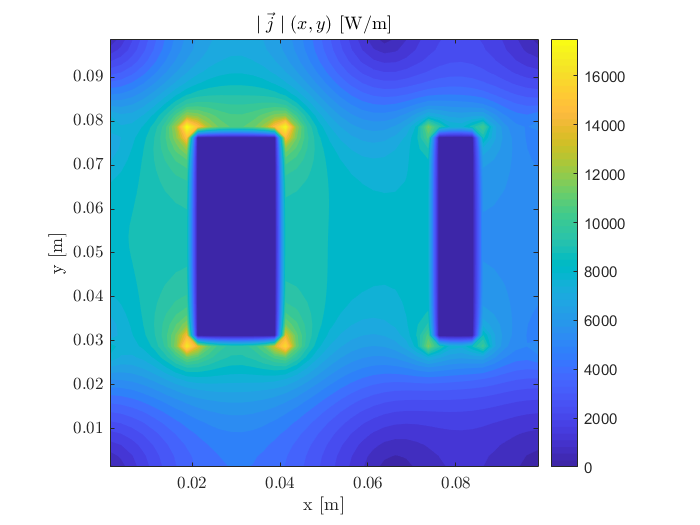


% Flux de chaleur :
figure
contourf(Xmid,Ymid,jnorm',30,'LineStyle','None')
hold on;
 
xlabel('x [m]')
ylabel('y [m]')
title('$\mid\vec{j}\mid(x,y)$ [W/m]')
colorbar
axis equal

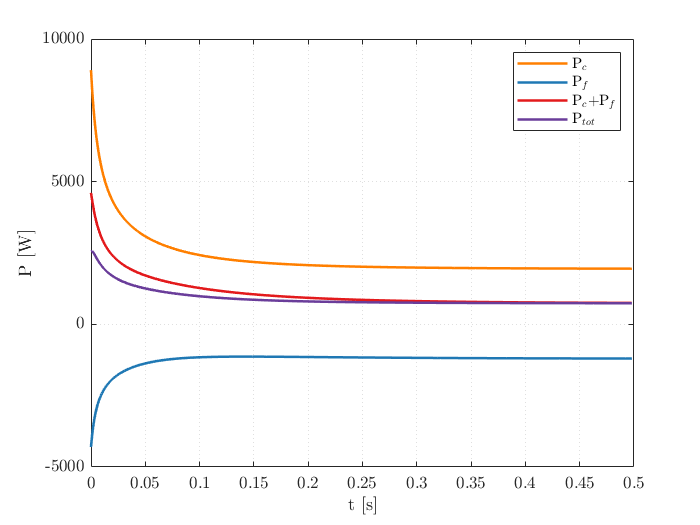


% Puissance :
figure
plot(t, Pc, '-','Color',M('dark orange'),'LineWidth',1.5);
hold on;
plot(t, Pf,'-','Color',M('dark blue'),'LineWidth',1.5);
plot(t, Pc + Pf,'-','Color',M('dark red'),'LineWidth',1.5);
plot(t, Ptot,'-','Color',M('dark purple'),'LineWidth',1.5);
xlabel('t [s]')
ylabel('P [W]')
legend('P$_c$', 'P$_f$', 'P$_c$+P$_f$', 'P$_{tot}$')
grid on